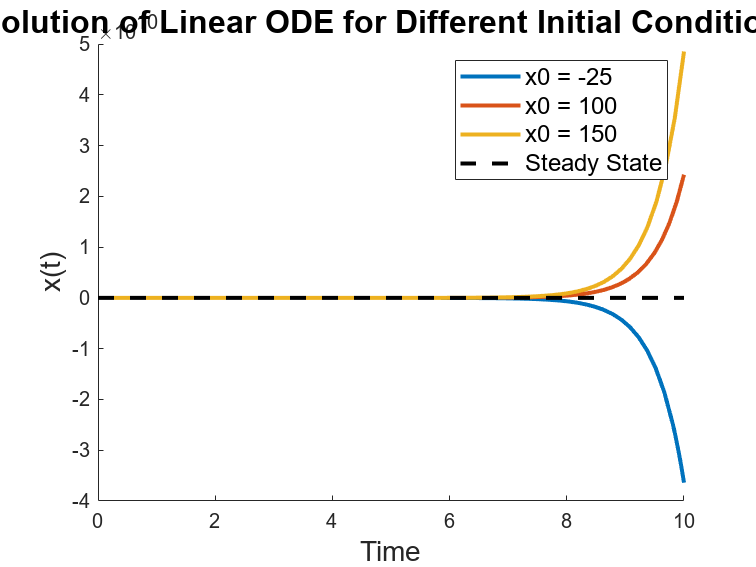

ans = 0

% Define the ODE function, time span, and initial conditions, respectively
ode_fun = @(t, x) 2*x - 100;
tspan = [0 10];
x0 = [-25, 100, 150]; 

% Run ODE per initial condition
figure;
hold on;
for i = 1:length(x0)
    [t, x] = ode45(ode_fun, tspan, x0(i));
    plot(t, x, 'LineWidth', 2);
end

% Plot Labels
x_steady_state = 50; 
plot(tspan, [x_steady_state, x_steady_state], '--', 'Color', 'k', 'LineWidth', 2); 

% Add legend and labels with larger font sizes
legend('x0 = -25', 'x0 = 100', 'x0 = 150', 'Steady State', 'FontSize', 12); 
xlabel('Time', 'FontSize', 14); 
ylabel('x(t)', 'FontSize', 14); 
title('Solution of Linear ODE for Different Initial Conditions', 'FontSize', 16); 

% Save the plot as a PDF
saveas(gcf, 'linear_ode_initial_conditions.pdf');0.

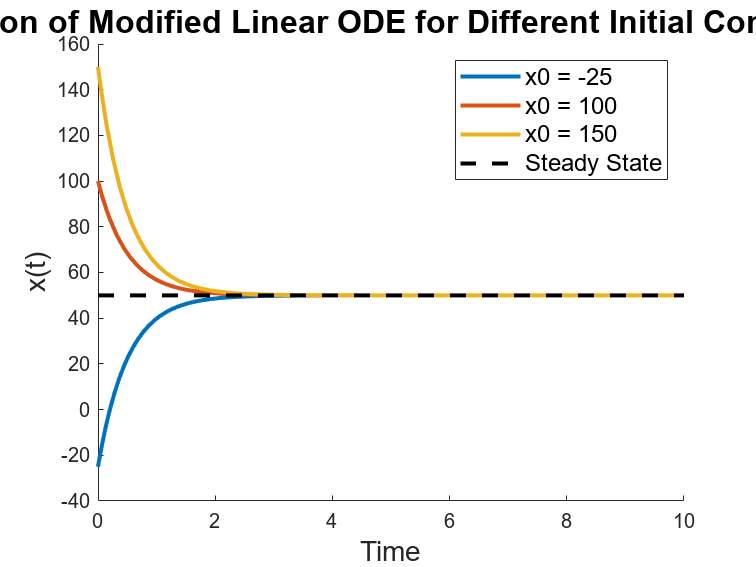

% Define the ODE function, time span, and initial conditions, respectively
ode_fun = @(t, x) -2*x + 100;
tspan = [0 10];
x0 = [-25, 100, 150];

% Run ODE per initial condition
figure;
hold on;
for i = 1:length(x0)
    [t, x] = ode45(ode_fun, tspan, x0(i));
    plot(t, x, 'LineWidth', 2); 
end

% Plot steady-state value as dashed line
x_steady_state = 50; 
plot(tspan, [x_steady_state, x_steady_state], '--', 'Color', 'k', 'LineWidth', 2); 

% Plot Labels
legend('x0 = -25', 'x0 = 100', 'x0 = 150', 'Steady State', 'FontSize', 12);
xlabel('Time', 'FontSize', 14); 
ylabel('x(t)', 'FontSize', 14); 
title('Solution of Modified Linear ODE for Different Initial Conditions', 'FontSize', 16); 

% Save the plot as a PDF
saveas(gcf, 'modified_linear_ode_initial_conditions.pdf');

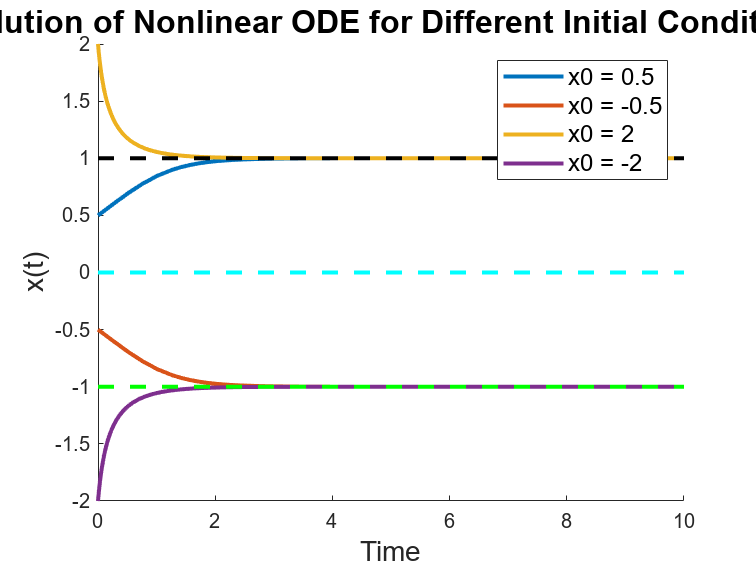

% Define the ODE function, time span, and initial conditions, respectively
ode_fun = @(t, x) x - x.^3;
tspan = [0 10];
x0 = [0.5, -0.5, 2, -2]; 

% Run ODE per initial condition
figure;
hold on;
for i = 1:length(x0)
    [t, x] = ode45(ode_fun, tspan, x0(i));
    plot(t, x, 'LineWidth', 2);
end

% Plot steady-state value as dashed line
x_steady_state = 1;
plot(tspan, [x_steady_state, x_steady_state], '--', 'Color', 'k', 'LineWidth', 2);
x_steady_state = 0;
plot(tspan, [x_steady_state, x_steady_state], '--', 'Color', 'c', 'LineWidth', 2); 
x_steady_state = -1;
plot(tspan, [x_steady_state, x_steady_state], '--', 'Color', 'g', 'LineWidth', 2); 

% Plot Labels
legend('x0 = 0.5', 'x0 = -0.5', 'x0 = 2','x0 = -2', 'FontSize', 12); 
xlabel('Time', 'FontSize', 14); 
ylabel('x(t)', 'FontSize', 14); 
title('Solution of Nonlinear ODE for Different Initial Conditions', 'FontSize', 16); 

% Save the plot as a PDF
saveas(gcf, 'nonlinear_ode_initial_conditions.pdf');